im1=double(imread('image1.png'))/255;

imshow(im1)

im1ycbcr = rgb2ycbcr(im1)
im1y = im1ycbcr(:,:,1);
im1cb = im1ycbcr(:,:,2);
im1cr = im1ycbcr(:,:,3);

imshow(im1y)


im1yd = bdct(im1y, [8 8])



% imshow(ibdct(im1yr, [8 8], size(im1y)))

% Q1=0.1;
% im1ydq = bquant(im1yd, Q1);
% im1ydr = brec(im1ydq, Q1);
% im1yr = ibdct(im1ydr, [8 8], size(im1y));
% figure, imshow(im1yr - im1y);

QL=repmat(1:8, 8, 1); QL=(QL+QL'-9)/8
k1=0.1; k2=0.3;
Q2=k1*(1+k2*QL);
im1ydq = bquant(im1yd, Q2);
im1ydr = brec(im1ydq, Q2);
im1yr = ibdct(im1ydr, [8 8], size(im1y));
figure, imshow(im1yr);

dist = mean((im1y(:)-im1yr(:)).^2)
psnr = 10*log10(1/dist)


% Source coding

p = ihist(im1ydq(:))

% Static huffman
% bits = huffman(p)
% bpp = bits/(length(im1y(:,1)) * length(im1y(1,:)))
pixels = length(im1y(:,1)) * length(im1y(1,:))
% Dynamic huffman
bits=0;
for k=1: size (im1ydq, 1)
    p = ihist(im1ydq(k,:));
    bits = bits + huffman(p);
end
bpp = bits/pixels

bits = sum(jpgrate(im1ydq, [8 8]));
bpp = bits/pixels


Code


% [psnr, bpp] = transcoder('image1.png', [40 40], 0.1, 0.1)

% psnr
% bpp

numberOfBlockSizes = 3;
blockSizeStart = 2;

numberOfStepSizes = 15

numberOfStepSizes = 15

stepSizeScale = 0.3

stepSizeScale = 0.3000

stepSizeStart = 0.1

stepSizeStart = 0.1000


res = zeros(2, numberOfStepSizes, numberOfBlockSizes);
size(res)

ans =      2    15     3


stepsize_lower = 0.01

stepsize_lower = 0.0100

stepsize_upper = 0.5

stepsize_upper = 0.5000

stepsizes = logspace(log10(stepsize_lower),log10(stepsize_upper),numberOfStepSizes);

for blockSize = 1:numberOfBlockSizes
    blockSizeStart^blockSize
    for stepSize = 1:numberOfStepSizes
        [psnr, bpp] = transcoder( ...
            'image1.png', ...
            [blockSizeStart^blockSize blockSizeStart^blockSize], ...
            stepsizes(stepSize), ...
            stepsizes(stepSize)*1.2, ...
            0.5, ...
            true, ...
            "bdct" ...
        );

            %             stepSize*stepSizeScale + stepSizeStart, ...
%             stepSize*stepSizeScale + stepSizeStart, ...
        res(:, stepSize, blockSize) = [psnr, bpp];
    end
end

ans = 2

ans = 4

ans = 8


res

res = res(:,:,1) =

   43.2233   42.0442   40.6998   39.1909   37.6031   35.7661   33.9603   32.1077   29.9877   27.9528   25.4607   23.2206   20.9511   20.0185   15.0672
    3.1484    2.7421    2.2469    1.8642    1.5818    1.3717    1.2153    1.0996    1.0097    0.9440    0.8948    0.8584    0.8310    0.8049    0.7947


res(:,:,2) =

   43.4356   42.4066   41.2614   40.0413   38.7701   37.4170   35.9649   34.4005   32.8994   31.2576   29.2706   27.9172   25.6157   23.4214   21.6449
    2.7780    2.2556    1.8001    1.3829    1.0742    0.9070    0.7279    0.5905    0.4837    0.4028    0.3428    0.2978    0.2654    0.2429    0.2245


res(:,:,3) =

   43.4989   42.5118   41.4420   40.3322   39.1882   37.9472   36.6834   35.3698   34.0071   32.6111   31.2178   29.8102   28.4266   26.9326   25.3299
    2.6580    2.1579    1.6974    1.3084    1.0123    0.7926    0.6296    0.4988    0.3972    0.3165    0.2518    0.1997    0.1625    0.1336    0.1135


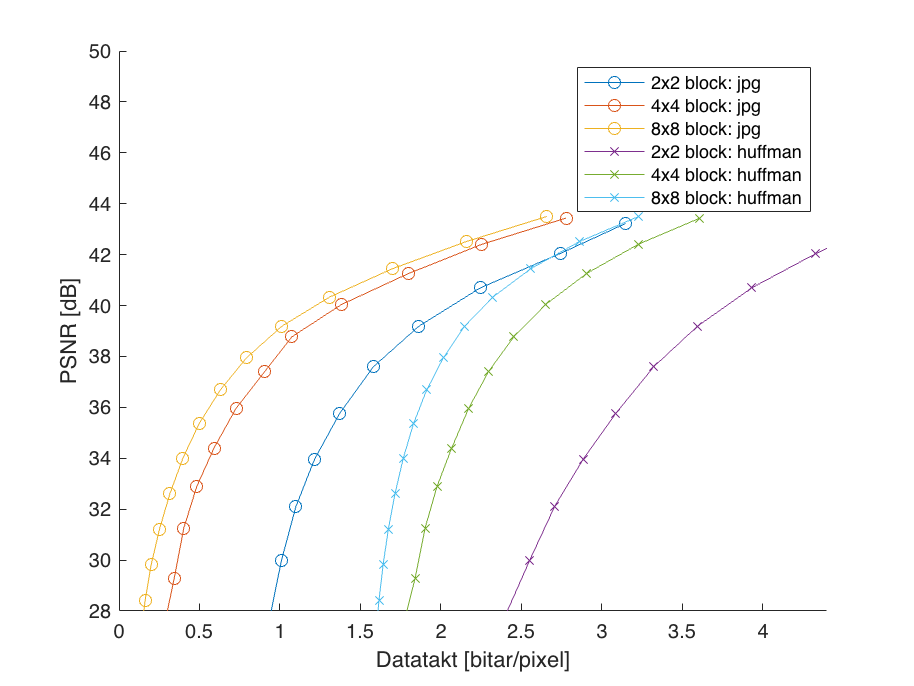

figure
% xlim([0, 1.4])
% ylim([28, 46])

xlim([0, 4.4])
ylim([28, 50])

hold on
for i = 1:numberOfBlockSizes
    plot(res(2,:,i), res(1,:,i),'-o')
end

for i = 1:numberOfBlockSizes
    plot(huffmanRes(2,:,i), huffmanRes(1,:,i),'-x')
end
legend('2x2 block: jpg', '4x4 block: jpg', '8x8 block: jpg', ...
       '2x2 block: huffman', '4x4 block: huffman', '8x8 block: huffman')
ylabel('PSNR [dB]')
xlabel('Datatakt [bitar/pixel]')
hold off

huffmanRes = res

huffmanRes = huffmanRes(:,:,1) =

   43.2233   42.0442   40.6998   39.1909   37.6031   35.7661   33.9603   32.1077   29.9877   27.9528   25.4607   23.2206   20.9511   20.0185   15.0672
    4.7379    4.3310    3.9336    3.5954    3.3245    3.0879    2.8844    2.7073    2.5521    2.4100    2.2749    2.1721    2.0540    1.9696    1.9287


huffmanRes(:,:,2) =

   43.4356   42.4066   41.2614   40.0413   38.7701   37.4170   35.9649   34.4005   32.8994   31.2576   29.2706   27.9172   25.6157   23.4214   21.6449
    3.6096    3.2274    2.9064    2.6517    2.4536    2.2976    2.1732    2.0674    1.9768    1.9023    1.8396    1.7856    1.7387    1.6975    1.6650


huffmanRes(:,:,3) =

   43.4989   42.5118   41.4420   40.3322   39.1882   37.9472   36.6834   35.3698   34.0071   32.6111   31.2178   29.8102   28.4266   26.9326   25.3299
    3.2292    2.8610    2.5581    2.3232    2.1481    2.0159    1.9123    1.8307    1.7669    1.7153    1.6740    1.6412    1.6159    1.5939    1.5760
